clear;
close all;
clc;
initime = clock;

addpath('../funcs/');
svfolder= "../../paper/figure1/";

Delta_e = 0.3;
Delta_i = 0.02; % none % changable
Iattn = 0.02;

time = 10000;
stimIn = 5000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

## Raw: Condition S1

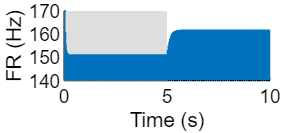

figure();
hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

fig = plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.1);

axis([0 time/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawS1', '-dpng', '-r600');
print(svfolder+'rawS1', '-depsc', '-r600');

## Raw: Condition S2

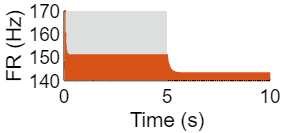

figure();

hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

fig = plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.1);
axis([0 time/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawS2', '-dpng', '-r600');
print(svfolder+'rawS2', '-depsc', '-r600');

## Raw: Condition S1S2

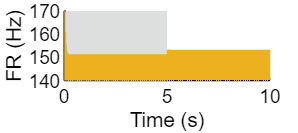

figure();

hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

fig = plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.1);
axis([0 time/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawS1S2', '-dpng', '-r600');
print(svfolder+'rawS1S2', '-depsc', '-r600');

## Raw: Condition S1S2+A1

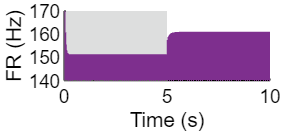

figure();

hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

fig = plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.1);
axis([0 time/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawS1S2+A1', '-dpng', '-r600');
print(svfolder+'rawS1S2+A1', '-depsc', '-r600');

## Raw: Condition S1S2+A2

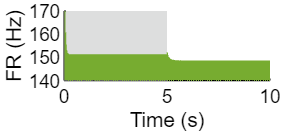

figure();

hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

fig = plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.1);
axis([0 time/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawS1S2+A2', '-dpng', '-r600');
print(svfolder+'rawS1S2+A2', '-depsc', '-r600');

## Raw overlap

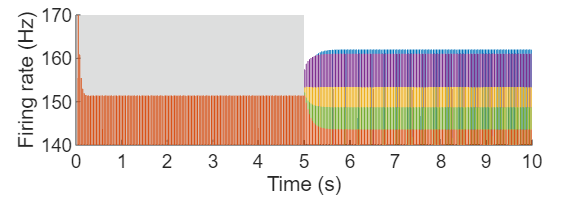

figure();

hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.1);
hold on;
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.1);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.1);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.1);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.1);

axis([0 time/1000 140 170]);
xticks([0 1 2 3 4 5 6 7 8 9 10]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
x0 = 0; y0 = 0; width = 8.9; height = 3;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawOverlap', '-dpng', '-r600');
print(svfolder+'rawOverlap', '-depsc', '-r600');

## Raw envelope

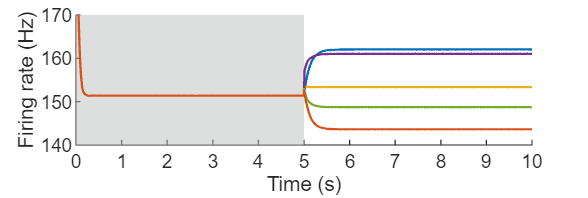

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

figure();
hold on;

recX = [0 stimIn/1000 stimIn/1000 0];
recY = [120 120 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

axis([0 time/1000 140 170]);
xticks([0 1 2 3 4 5 6 7 8 9 10]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
x0 = 0; y0 = 0; width = 8.9; height = 3;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawEnv', '-dpng', '-r600');
print(svfolder+'rawEnv', '-depsc', '-r600');

## center freq

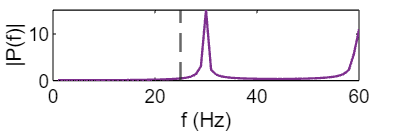

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

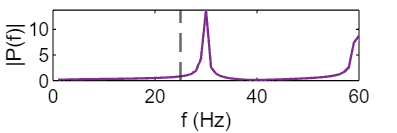


maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,1:100000,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);